# Solar radiation, Fraunhofer lines, Earth lines, Daylight basis

Graphs showing the properties of daylight and solar radiation.

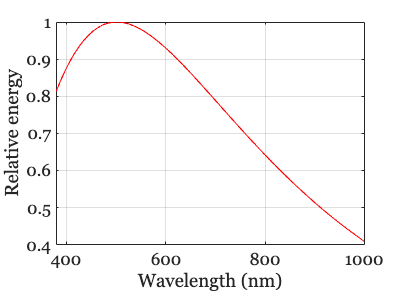

wave = 380:5:1000;
solar = ieReadSpectra('solarSpectrum',wave);
ieFigure;
plot(wave,solar);
grid on; xlabel('Wavelength (nm)'); ylabel('Relative energy');

The comment fields contain multiple Fraunhofer and Earth  atmosphere absorption lines.  

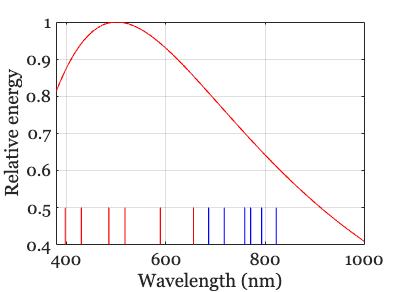

allLines = comment{4};

% These are some examples for plotting.
fSelectSolar = comment{5};
fSelectEarth = comment{6};

solarLines = allLines(fSelectSolar(:),:);
solarLines = cell2mat(solarLines(:,3))';

earthLines = allLines(fSelectEarth(:),:);
earthLines = cell2mat(earthLines(:,3))';

hold on;
ylim = get(gca,'ylim');
x = earthLines;
for ii=1:numel(x)
    line([x(ii),x(ii)],[ylim(1),ylim(1)+0.1],'Color','b');    
end

x = solarLines;
for ii=1:numel(x)
    line([x(ii),x(ii)],[ylim(1),ylim(1)+0.1],'Color','r');    
end

grid on; 
xlabel('Wavelength (nm)'); ylabel('Relative energy');

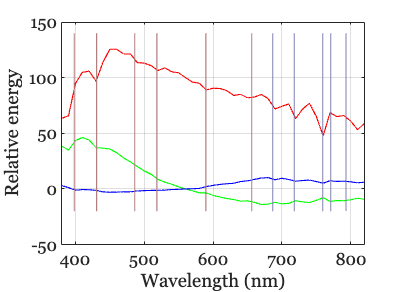

wave = 380:5:820;
dayBasis = ieReadSpectra('cieDaylightBasis',wave);
ieFigure;
plot(wave,dayBasis);

hold on;
ylim = get(gca,'ylim');
x = earthLines;
for ii=1:numel(x)
    line([x(ii),x(ii)],[ylim(1),ylim(2)],'Color',[0.5 0.5 0.7]);    
end

x = solarLines;
for ii=1:numel(x)
    line([x(ii),x(ii)],[ylim(1),ylim(2)],'Color',[0.7 0.5 0.5]);    
end

grid on; 
xlabel('Wavelength (nm)'); ylabel('Relative energy');
set(gca,'xlim',[380,820])